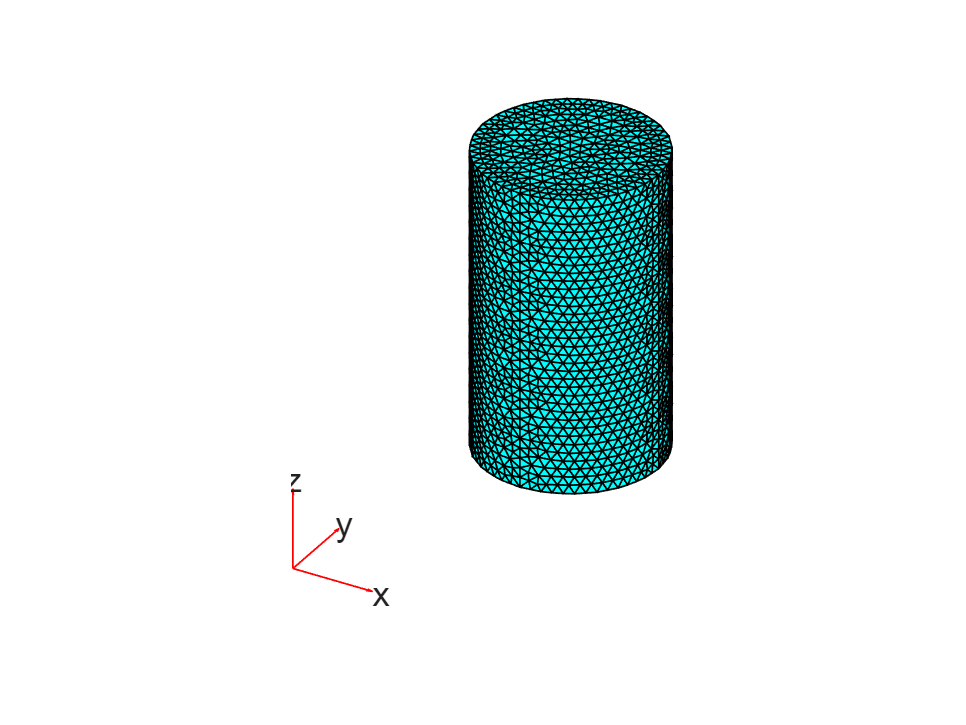

C1 = [1;  0; 0;   0.21];

g = decsg(C1);

NTM = 6;

gm2D = fegeometry(g);
gm3D = extrude(gm2D,ones(1,NTM)*0.70/NTM);
gm3D = generateMesh(gm3D,Hmin=0.02);
pdemesh(gm3D)

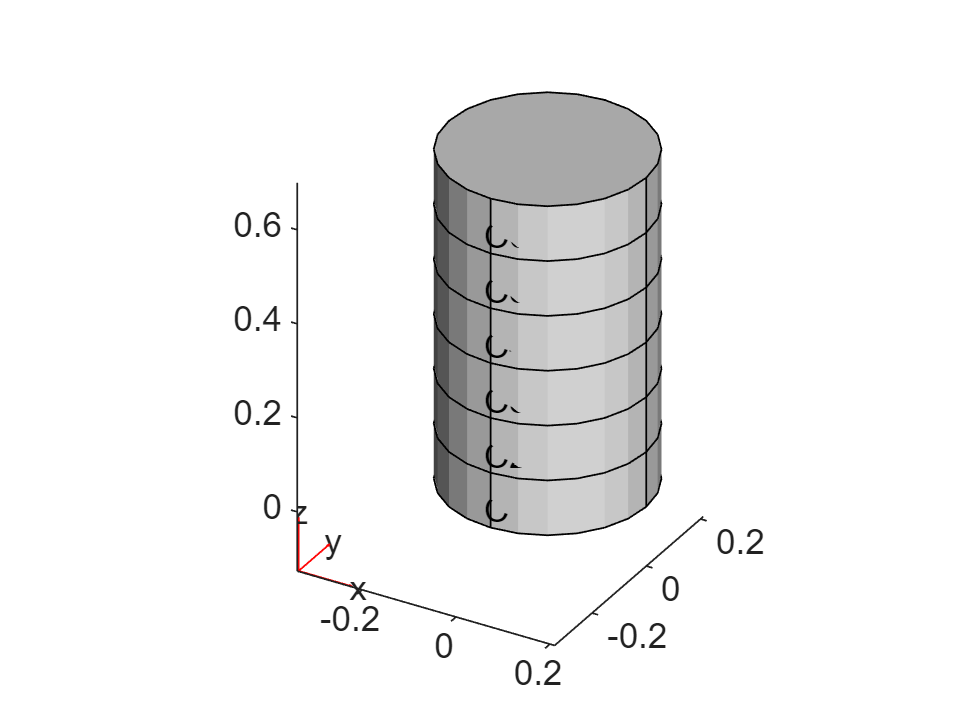

pdegplot(gm3D,'CellLabels','on')

cnodes = cell(1,NTM);
for i = 1:NTM
    cnodes{i} = findNodes(gm3D.Mesh,'region','Cell',i);
end
T = ones(size(gm3D.Mesh.Nodes,2),1);


modelname = "Models\HeightDistributedThermalMass.slx";
load_system(modelname);
out = sim(modelname);
Tsim = out.logsout{1}.Values;
close_system(modelname);

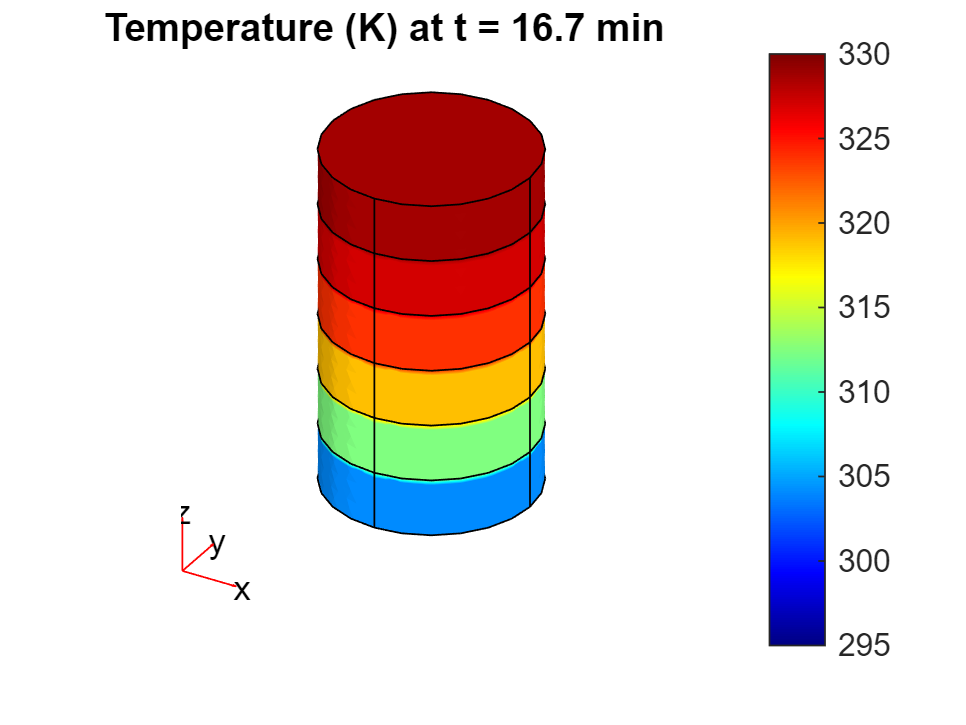



% Create a figure window
figure;
% (Position=[0 0 2000 500])

% Set the animation frame rate
frameRate = 10; % frames per second

% Compute the number of frames
numFrames = length(Tsim.Time);

% Set the animation duration
duration = numFrames/frameRate; % seconds

% h = animatedline('LineWidth',2,'Color','b');

% Create a VideoWriter object
video = VideoWriter('./Visualization/TemperatureAnimationCell.mp4', 'MPEG-4');
video.FrameRate = frameRate;

% Open the VideoWriter object
open(video);

% Loop through each frame
for frame = 1:numFrames
    
    for i=1:NTM
        T(cnodes{i}) = Tsim.Data(frame,i);
    end
    pdegplot(gm3D,'FaceAlpha',0); hold on;
    pdeplot3D(gm3D.Mesh,'ColorMapData',T);
    ha = gca;
    hc = ha.Children;
    [hc(2:5).Visible] = deal('off');
    hold off;
    titlestring = sprintf('Temperature (K) at t = %.1f min',...
        Tsim.Time(frame)/60);
    title(titlestring);

    clim([295 330]);


    % Write the current frame to the video file
    writeVideo(video, getframe(gcf));
end

close(video);